# **Fitting the Dynamics of the traces **

### Import the datasets

if ismac
    cd '/Users/binxu/Library/Mobile Documents/com~apple~CloudDocs/Data_Transport/'
elseif ispc
    cd 'C:\Users\binxu\iCloudDrive\Data_Transport'
end
load('raw_traces.mat')
load('tile_pos2.mat')
load('tile_space.mat')
load('tile_traces.mat')
if ismac
    cd '/Users/binxu/Holy_Optical_Imaging/matlab_visualization'
elseif ispc
    cd 'D:\Light-Sheet-Data-Processing-Script\matlab_visualization'
end
load('image_vol.mat')
tile_idx = cell2mat(tile_idx); 
raw_traces = raw_traces';

### Preprocessing

Do low pass filtering, and then hierachical clustering to get the sorting index vector

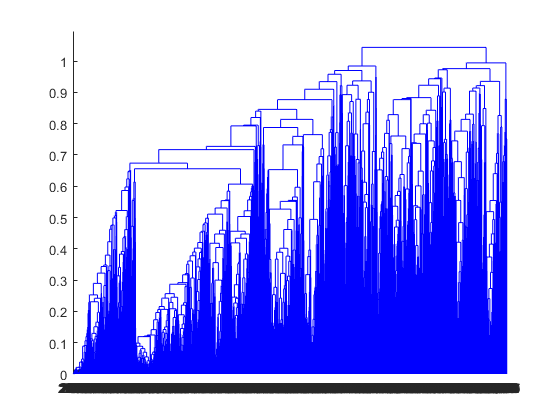

lpf_zscore_arr = zeros(size(zscore_arr)); % Lowpass filtered version of zscore trace
for i=1:size(zscore_arr)
    trace = zscore_arr(i,:);
    lpf_zscore_arr(i,:) = filter1('lp',double(trace), 'fs', 20, 'fc', 1);
end
Z = linkage(lpf_zscore_arr,'average','correlation');
[~, T, outperm] = dendrogram(Z,0); 

## First order model

Fit the dynamical matrix 


$$x\left(t+1\right)=\mathit{Wx}\left(t\right)$$


connect_coef = ( zscore_arr(outperm, 2:end)  ) / zscore_arr(outperm, 1:end-1); 

## Second order model


$$x\left(t+1\right)=W_1 x\left(t\right)+W_{2\;} x\left(t-1\right)$$


connect_coef_t2 = zscore_arr(outperm, 3:end) / [zscore_arr(outperm, 1:end-2); 
                                                zscore_arr(outperm, 2:end-1)];                                             

## Compute the estimated traces and automonous traces

Enter the predicted 

pred_time_slic = 11400:14000;

%% Predict part of the trace
autonom_zscore_arr = zeros(size(zscore_arr, 1), length(pred_time_slic));
autonom_zscore_arr(:,1) = zscore_arr(outperm, pred_time_slic(1)); 
for t = 2:length(pred_time_slic)
    autonom_zscore_arr(:,t) = connect_coef * autonom_zscore_arr(:,t-1);
end
%% 2nd order autonom ds result
autonom_zscore_arr_o2 = zeros(size(zscore_arr, 1), length(pred_time_slic));
autonom_zscore_arr_o2(:,1:2) = zscore_arr(outperm, pred_time_slic(1:2)); 
for t = 3:length(pred_time_slic)
    autonom_zscore_arr_o2(:, t) = connect_coef_t2 * [autonom_zscore_arr_o2(:,t-2); ...
                                                     autonom_zscore_arr_o2(:,t-1)];
end

### Visualize the error of estimation and autonomous dynamics

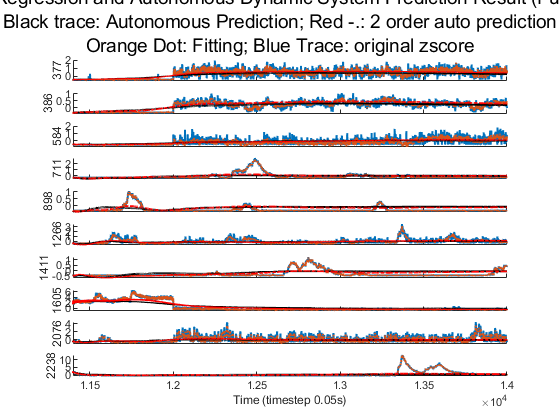

samp_num = 10;
rand_idx = sort(randperm(size(zscore_arr,1), samp_num)); 
figure();clf;hold on
for i=1:samp_num
    subplot(samp_num,1,i);
    hold on;
    plot(pred_time_slic, zscore_arr(outperm(rand_idx(i)), pred_time_slic), 'LineWidth', 1.5)
    plot(pred_time_slic, estimated_zscore_arr(rand_idx(i), pred_time_slic), ':', 'LineWidth', 1.5)
    plot(pred_time_slic, autonom_zscore_arr(rand_idx(i), :), 'k-', 'LineWidth', 1.5)
    plot(pred_time_slic, autonom_zscore_arr_o2(rand_idx(i), :), 'r-.', 'LineWidth', 1.5)
%     ylim([-1,10])
    xlim([pred_time_slic(1), pred_time_slic(end)])
    ylabel(num2str(rand_idx(i)))
    if i~=samp_num
        xticklabels([])
    else
%         xticks(0:1000:24000)
        xlabel('Time (timestep 0.05s)')
    end
end
suptitle({'Compare Regression and Autonomous Dynamic System Prediction Result (Full Network)',
                'Black trace: Autonomous Prediction; Red -.: 2 order auto prediction', 
                'Orange Dot: Fitting; Blue Trace: original zscore'})